# Using and Comparing Pre-Trained Models

Many models created by experts and trained on extensive, general-purpose image datasets are available in MATLAB. These models vary in size and complexity, often resulting in variations in accuracy and prediction speed.

In this reading, you will compare two pre-trained models:

- ResNet-18

- ResNet-50

The number in the network names (e.g. 18 and 50) refers to the number of convolutional layers in each network.

## Installing and Viewing Networks in the Deep Network Designer App

Use the Apps tab to open each of these networks in the Deep Network Designer.

The first time you open a network, you may have to install it by clicking the "Install" button:

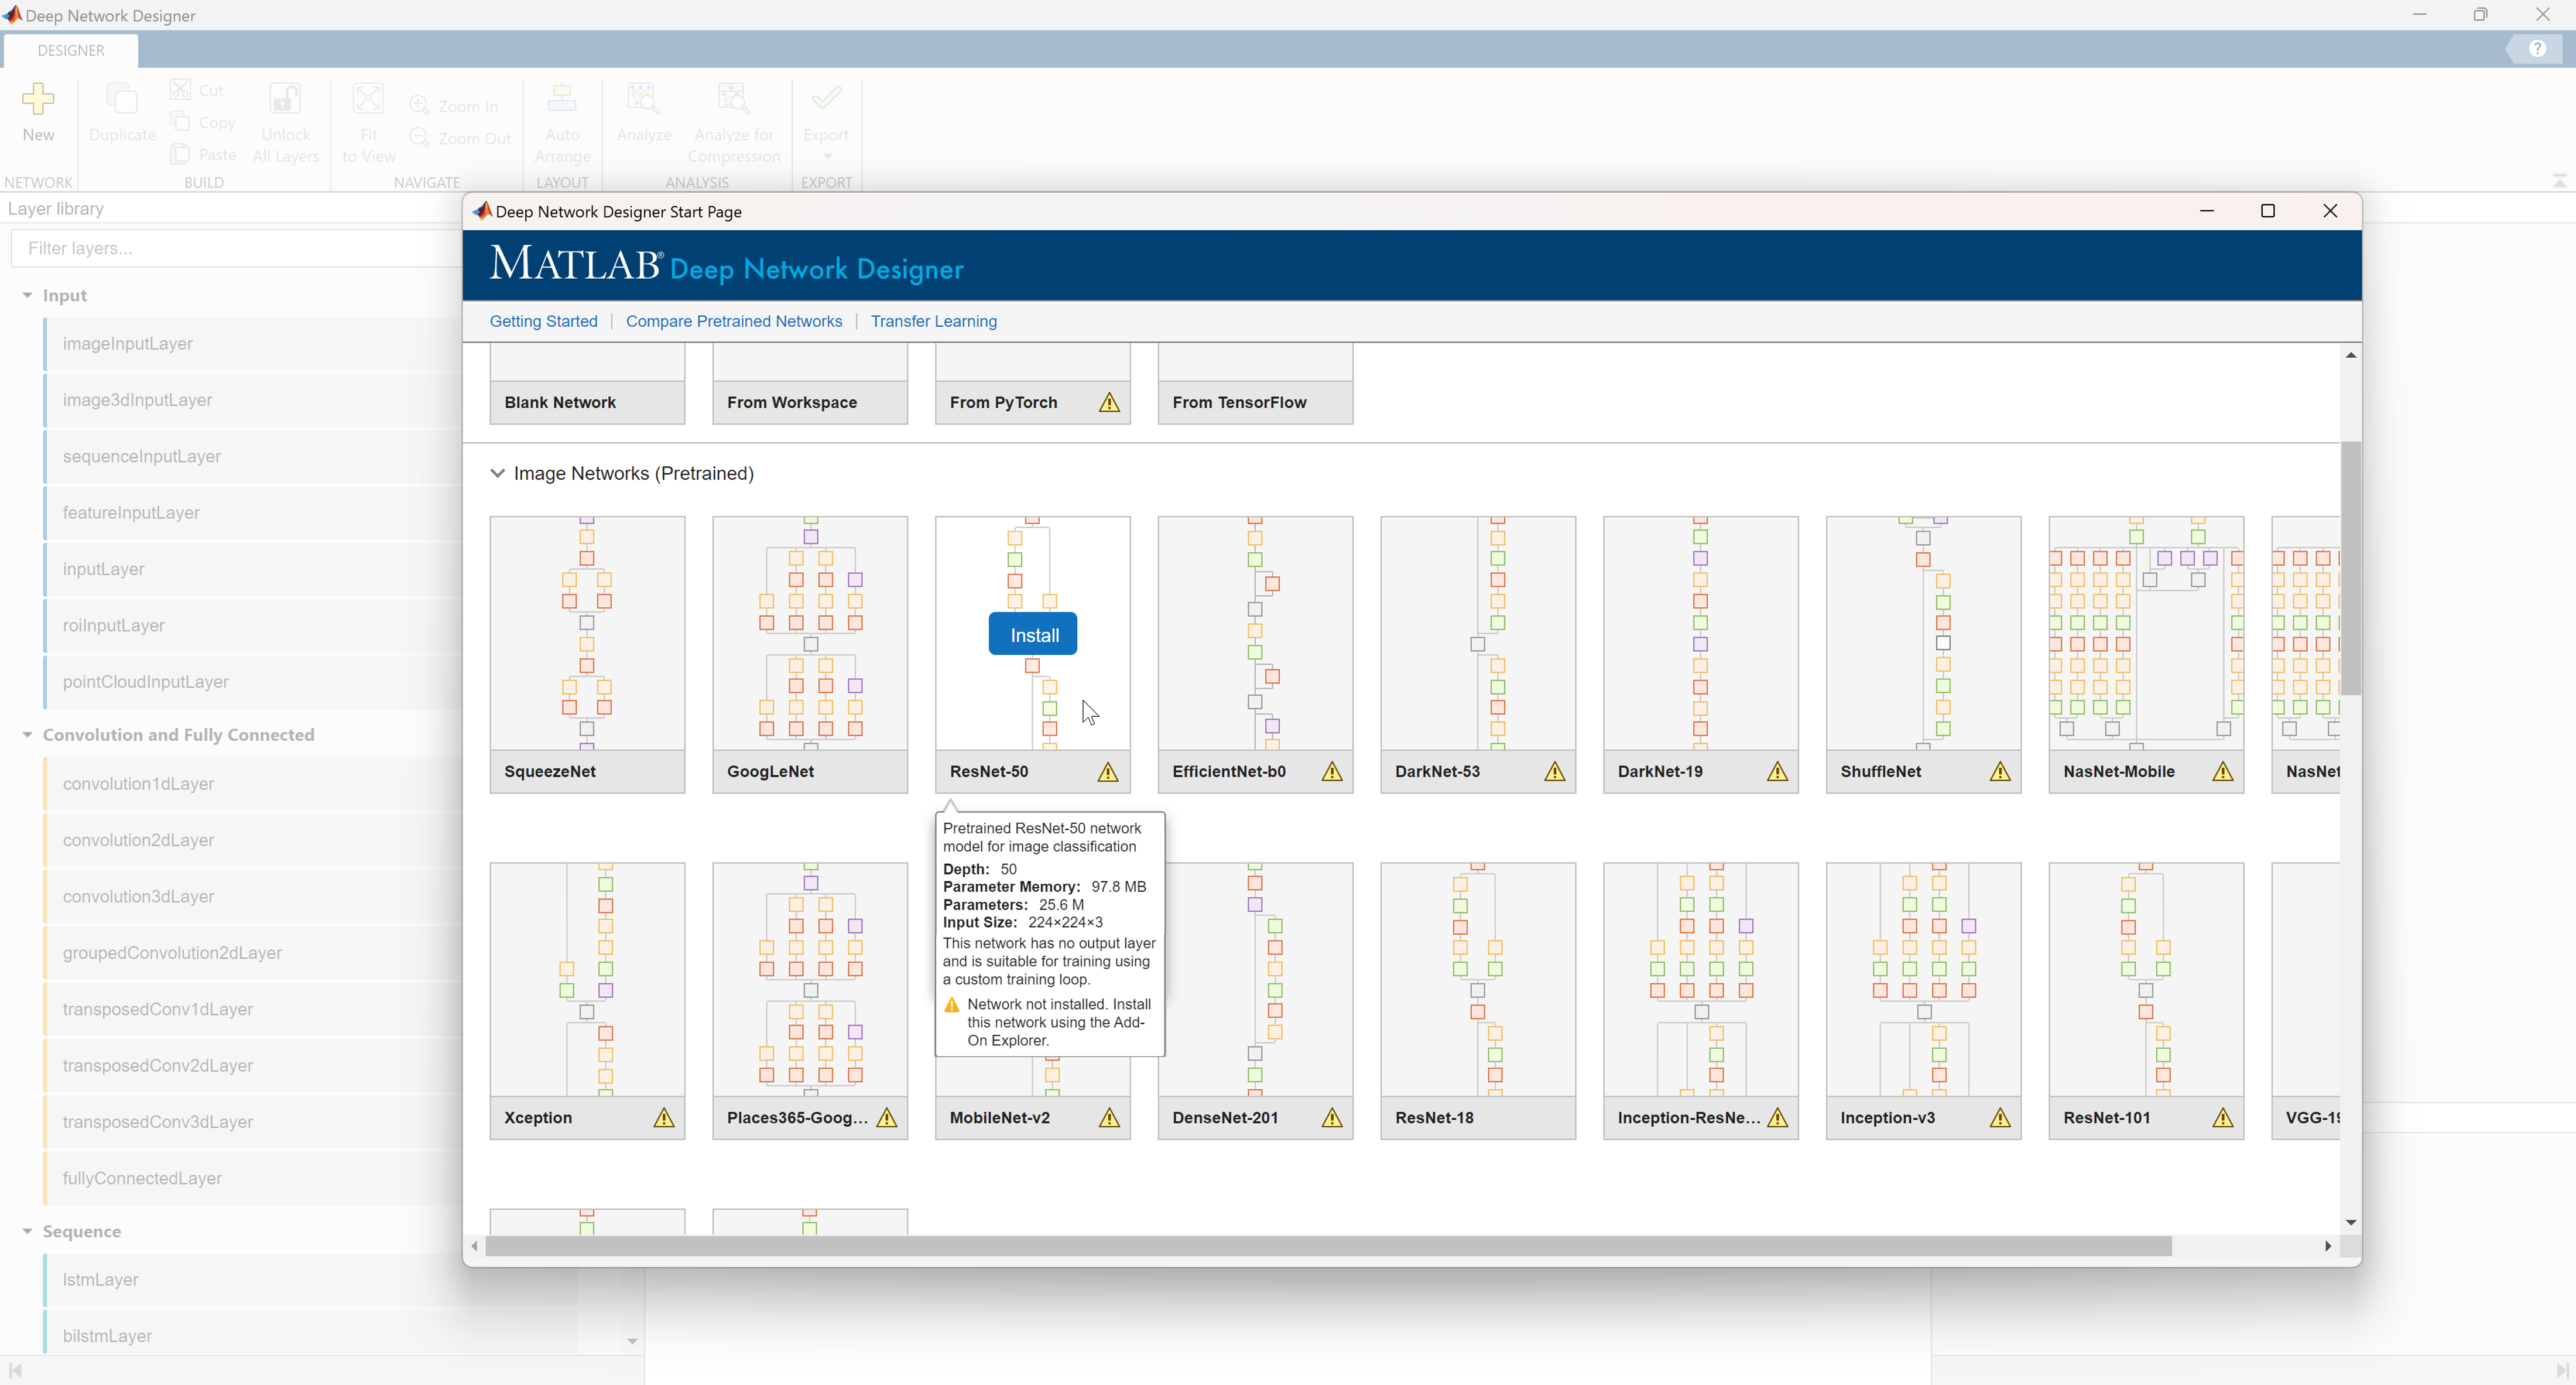

Using the app, consider the relative sizes of ResNet-18 and ReNet-50. Which has more layers? What layers do they share? 

## Loading Networks with Code

In addition to viewing pre-trained models in the Deep Network Designer app, you can also load installed models into the workspace using the [imagePretrainedNetwork](https://www.mathworks.com/help/deeplearning/ref/imagepretrainednetwork.html#mw_a8067bf1-f49d-4e4a-9190-f849c01dac73) function.

**Note:** If you encounter an error during this step, you likely need to return to the previous step and install the model.

[net18, classes18] = imagePretrainedNetwork("resnet18");
[net50, classes50] = imagePretrainedNetwork("resnet50");

In addition to the network itself, `imagePretrainedNetwork` has an optional second output that specifies the classes it was trained on. These are usually general image classes spanning a wide range of categories.

classes18

classes18 = 1000×1 string array
    "tench"
    "goldfish"
    "great white shark"
    "tiger shark"
    "hammerhead"
    "electric ray"
    "stingray"
    "cock"
    "hen"
    "ostrich"
    "brambling"
    "goldfinch"
    "house finch"
    "junco"
    "indigo bunting"
    "robin"
    "bulbul"
    "jay"
    "magpie"
    "chickadee"
    "water ouzel"
    "kite"
    "bald eagle"
    "vulture"
    "great grey owl"
    "European fire salamander"
    "common newt"
    "eft"
    "spotted salamander"
    "axolotl"


### Compare Model Sizes

The number of layers in a network greatly impacts the number of learnable parameters and the model's size. Extra complexity results in larger models and slower prediction speeds, but for some applications can give more accurate results.

Run this code to compare your models' sizes.

whos net18 net50

  Name       Size                Bytes  Class        Attributes

  net18      1x1              47144683  dlnetwork              
  net50      1x1             104577526  dlnetwork              



## Accessing Network Layers

Each of these pretrained networks is imported as a `dlnetwork` object. This object contains information about the network, including:

- `Layers:` a `layer` array specifying the network layers.

- `Connections:` a table describing how the layers interact. In more complex models, the layers are not always connected linearly:

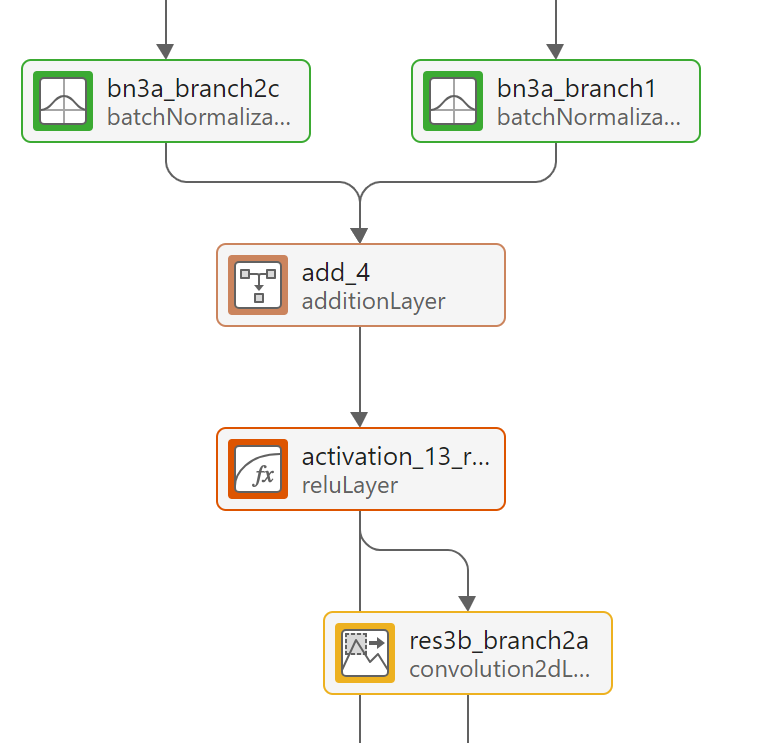

You can access the network layer details using dot notation. For example, the first layer is the input layer:

net18.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zscore'
    NormalizationDimension: 'auto'
                      Mean: [1×1×3 single]
         StandardDeviation: [1×1×3 single]


The last few layers of a classification network are generally the full-connected and softmax layers:

net18.Layers(end-1)

ans =   FullyConnectedLayer with properties:

          Name: 'fc1000'

   Hyperparameters
     InputSize: 512
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×512 single]
          Bias: [1000×1 single]

  Show all properties


net18.Layers(end)

ans =   SoftmaxLayer with properties:

    Name: 'prob'


### Determining Network Complexity

The number of layers is also a good metric of a given network's complexity. How many more layers does ResNet-50 have than ResNet-18?

length(net18.Layers)

ans = 70

length(net50.Layers)

ans = 176

### Determining Image Input Size 

You can also explore layer-specific properties of the network. For example, you can determine each network's expected image input size:

net18.Layers(1).InputSize

ans =    224   224     3


net50.Layers(1).InputSize

ans =    224   224     3


Because these networks have the same `InputSize`, we only need to resize images once to use them in both networks.

## Using Pre-Trained Networks to Classify Images

Now that we know the image input size, make a prediction for the same image from the fastener dataset with both networks and compare the results. The `tic` and `toc` functions are used to compare prediction speeds.

Read in and resize the image:

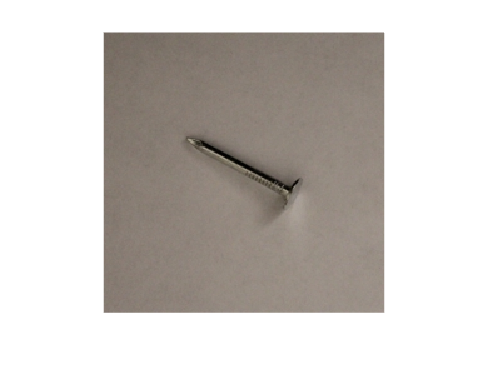

imgNail = imread("fastener0506.jpg");
imgNail = imresize(imgNail,[224 224]);
imshow(imgNail)

Make predictions for this image using the `minibatchpredict` function:

tStart = tic;
prediction18 = minibatchpredict(net18,imgNail);
prediction18Class = scores2label(prediction18,classes18);
tElapsed = toc(tStart);
results18 = "ResNet-18 prediction: " + string(prediction18Class) + newline + "ResNet-18 Prediction time: " + round(tElapsed,2) + " seconds"

results18 =     "ResNet-18 prediction: nail
     ResNet-18 Prediction time: 0.4 seconds"



tStart = tic;
prediction50 = minibatchpredict(net50,imgNail);
prediction50Class = scores2label(prediction50,classes50);
tElapsed = toc(tStart);
results50 = "ResNet-50 prediction: " + string(prediction50Class) + newline + "ResNet-50 Prediction time: " + round(tElapsed,2) + " seconds"

results50 =     "ResNet-50 prediction: nail
     ResNet-50 Prediction time: 0.27 seconds"


How did each model perform? Which network had a faster prediction speed? 

The differences might seem small here, but remember that many applications require predictions for thousands of images. Those fractions of seconds add up quickly!

Feel free to install and try out different pre-trained models. A description of pre-trained classification models available in MATLAB can be found [here](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html). You may notice that pre-trained models often successfully identify a broad, general class. However, you'll soon see how to re-train them for tailored categories, such as identifying this nail as a $1\frac{1}{4}$ inch roofing nail.

*Copyright 2025 The MathWorks, Inc.*